clear
clc

VONNPath = pwd;
CS670Path = fullfile(VONNPath, "Patrick Do/CS670");

testDataOpt = "AVOData_Psy_80Train_20Test_V1R3S_Test_1PerClass";
testDataFolder = fullfile(CS670Path, "Data_CS670", testDataOpt);

% Load Test Data
imdsVal = imageDatastore(testDataFolder, ...
        "IncludeSubfolders",true, "LabelSource", "foldernames", ...
        "FileExtensions", ".mat", "ReadFcn",@loadPD);

classes = 2×1 categorical array
     AD 
     NC 


Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:02 |       56.25% |       50.00% |       0.7825 |       0.7751 |          0.0100 |
|       5 |          30 |       00:00:52 |       78.12% |      100.00% |       0.4269 |       0.0686 |          0.0100 |
|       9 |          50 |       00:01:27 |       87.50% |              |       0.2284 |              |          0.0100 |
|      10 |          60 |       00:01:44 |       92.19% |      100.00% |       0.1763 |       0.0059 |          0.

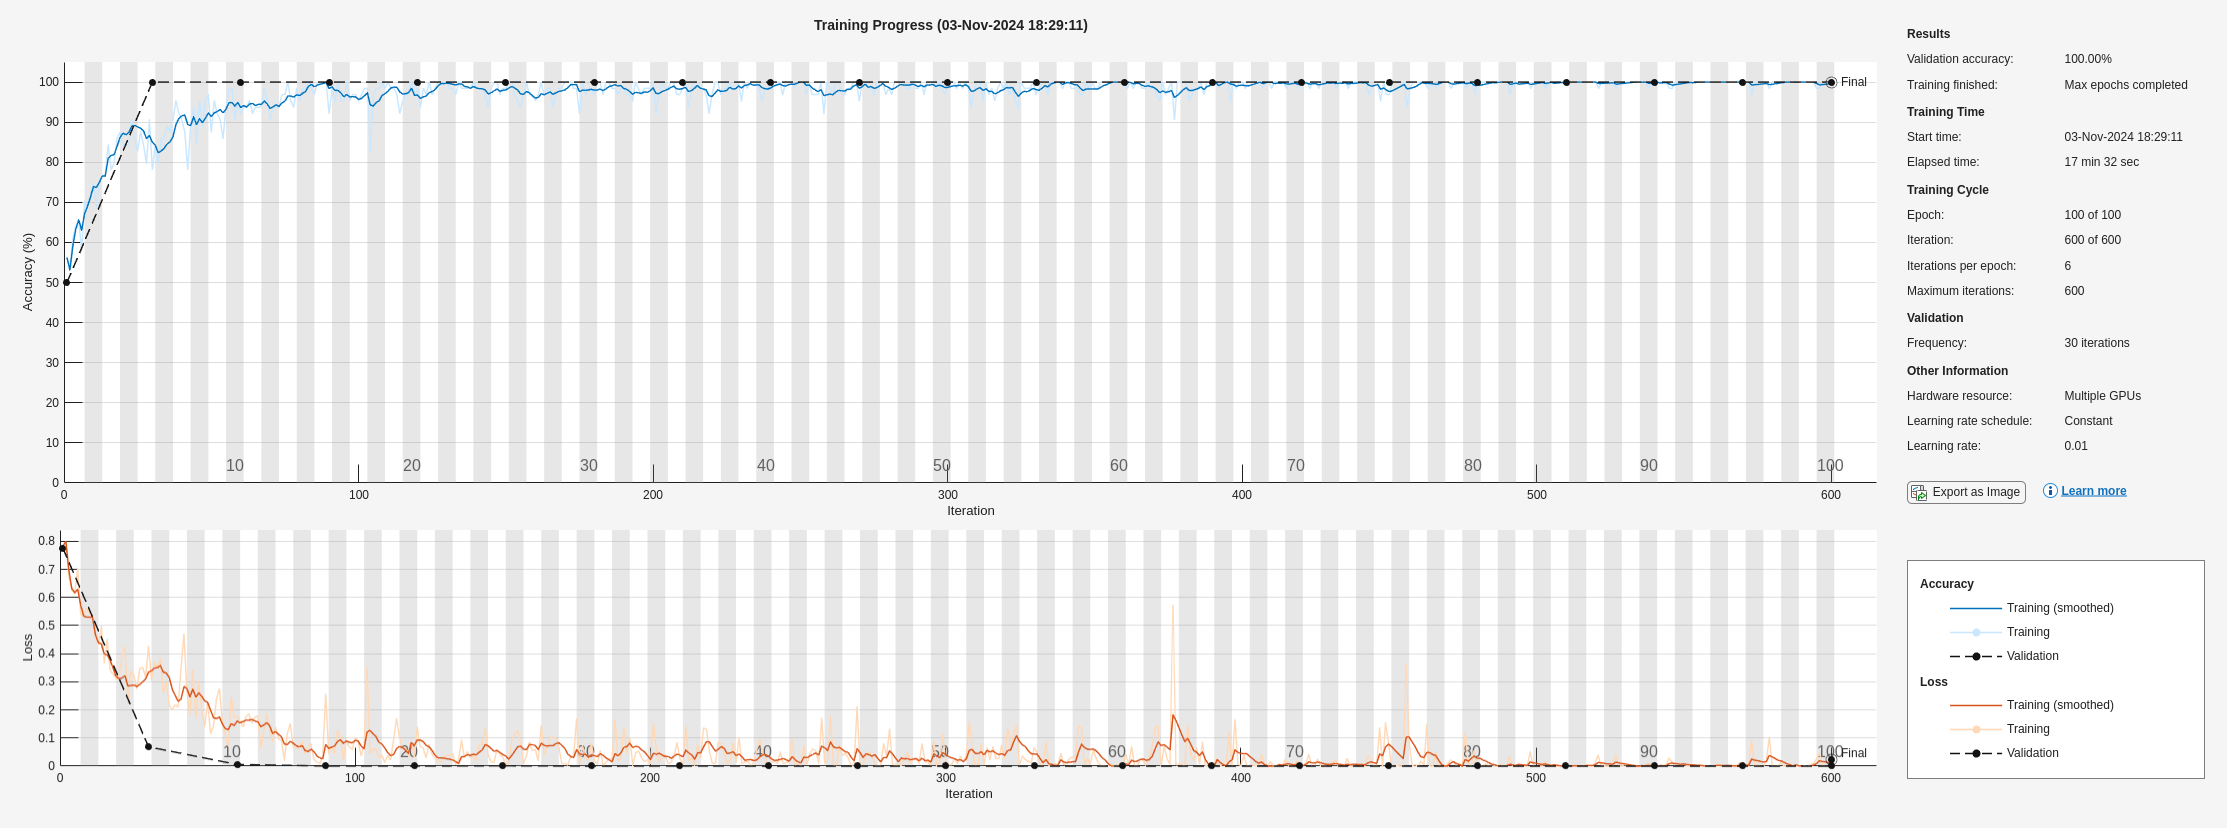

for k=2:2
    for dataOpt = ["AVOData_Psy_80Train_20Test_V1R3S_Train_200PerClass"]%, "AVOData_Psy_80Train_20Test_V1R3S_Train_250PerClass", "AVOData_Psy_80Train_20Test_V1R3S_Train_300PerClass"]
        dataFolder = fullfile(CS670Path, "Data_CS670", dataOpt);
        % Load Train Data
        imdsTrain = imageDatastore(dataFolder, ...
                "IncludeSubfolders",true, "LabelSource", "foldernames", ...
                "FileExtensions", ".mat", "ReadFcn",@loadPD);

        classes = unique(imdsTrain.Labels)
        inputSize = [91 109 91 1];
        outputSize = length(classes);
        dropRate = 0.4;
        classWeights =  [1 1];
        layers = resnet101_3DTNV_Retrained(inputSize, outputSize, dropRate, classes, classWeights);
        
        curDate = "Oct30";
        savePath = fullfile(CS670Path, "Results_CS670", dataOpt);
        if ~exist(savePath, "dir")
            mkdir(savePath);
        end
        filename = fullfile(strcat("resnet101Retrained_baseline_", curDate, "_trial_", num2str(k)));
        checkpointPath = fullfile(savePath, filename);

        maxEpoch = 100;
        options = trainingOptions('sgdm', ...
            'ExecutionEnvironment','multi-gpu',...
            'InitialLearnRate',0.01, ...
            'L2Regularization',0.0005,...
            'GradientThreshold',0.05, ...
            'MaxEpochs',maxEpoch, ...
            'Shuffle','every-epoch', ...
            'ValidationData',imdsVal, ...
            'ValidationFrequency',30, ...
            'Verbose',true,...
            'MiniBatchSize',64,...
            'ValidationPatience',Inf,...
            'Plots','training-progress', ...
            'OutputNetwork','last-iteration');
        
        net = trainNetwork(imdsTrain, layers, options);
           
        save(fullfile(savePath, strcat(filename, ".mat")), "net", "options")
    end
end

% % Define the output function
% function stop = saveModelEveryDesiredEpochs(info, numEpoch, filename)
%     stop = false; % Continue training
%     if mod(info.Epoch, numEpoch) == 0
%         modelFilename = strcat(filename, "_epoch_", num2str(info.Epoch));
%         net = info.TrainedNetwork;
%         % Save the model
%         save(modelFilename, 'info', 'net');
%     end
% end